Initialize the grid, bathymetry etc.

[t_mask, e1u, e2v, e3w0, totaldepth] = initialize_mesh('mesh_mask201702.nc');

Get the initial data.

[u, v, w, tcorrs, t_coords, u_coords, v_coords, w_coords, deltat, nextindex, e3w] = ...
    get_initial_data(totaldepth, e3w0);

useindex = 1

Set up the initial grid of points

tc=t_coords(1, 1);
zc=25;  % add one to python
yc=446; % add one to python
xc=304;  % add one to python
yi = grid_points(t_coords, deltat, t_mask, tc, zc, yc, xc);

good = int8
23

tmax = 48

tmax = 48

Do a short integration

to = tc;
dt = deltat/10.;
tf = to + 1.5*deltat;
tspan = [to tf];
[allt,ally] = ode45(@(t,y) derivatives(t, y, deltat, t_mask, e3w, e2v, e1u, w_coords, v_coords, u_coords, w, v, u),...
    [to tf], yi);

And now run for longer, updating the arrays as necessary

for count=4:tmax
    [tcorrs, u_coords, v_coords, w_coords, u, v, w, nextindex, e3w] = ...
        update_arrays(totaldepth, e3w0, e3w, tcorrs, u_coords, v_coords, w_coords, u, v, w, ...
                      deltat, nextindex);
    to = tf;
    tf = tf + deltat;
    tspan = [to tf];
    yni = ally(end, :);
    [t1, y1] = ode45(@(t,y) derivatives(t, y, deltat, t_mask, e3w, e2v, e1u, w_coords, v_coords, u_coords, w, v, u),...
    [to tf], yni);
    allt = cat(1, allt, t1);
    ally = cat(1, ally, y1);
end

nextindex = 4

useindex = 4

nextindex = 5

useindex = 5

nextindex = 6

useindex = 6

nextindex = 7

useindex = 7

nextindex = 8

useindex = 8

nextindex = 9

useindex = 9

nextindex = 10

useindex = 10

nextindex = 11

useindex = 11

nextindex = 12

useindex = 12

nextindex = 13

useindex = 13

nextindex = 14

useindex = 14

nextindex = 15

useindex = 15

nextindex = 16

useindex = 16

nextindex = 17

useindex = 17

nextindex = 18

useindex = 18

nextindex = 19

useindex = 19

nextindex = 20

useindex = 20

nextindex = 21

useindex = 21

nextindex = 22

useindex = 22

nextindex = 23

useindex = 23

nextindex = 24

useindex = 24

nextindex = 25

nextindex = 26

nextindex = 27

nextindex = 28

nextindex = 29

nextindex = 30

nextindex = 31

nextindex = 32

nextindex = 33

nextindex = 34

nextindex = 35

nextindex = 36

nextindex = 37

nextindex = 38

nextindex = 39

nextindex = 40

nextindex = 41

nextindex = 42

nextindex = 43

nextindex = 44

nextindex = 45

nextindex = 46

nextindex = 47

nextindex = 48

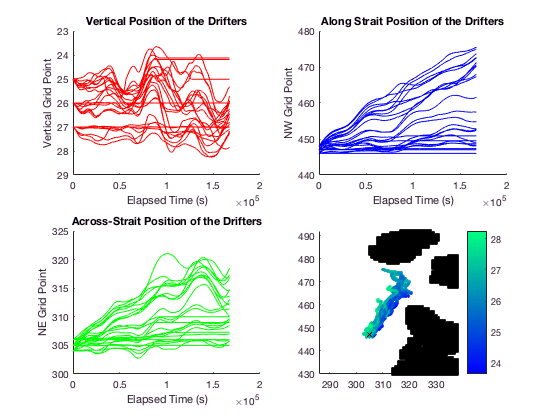

four_up_plot(allt, ally, t_mask, tc)

save('mytrajectories_17apr16.mat', 'allt', 'ally');